# Computing the controller Hr(s) using the logarithmic diagrams

### Compute and declare my transfer function

The transfer function has the following form:


$$H_f \left(s\right)=\frac{K_f }{s\left(T_f s+1\right)}$$


Knowing that my values are Kf = 4 and  Tf = 8, the function becomes:


$$H_f \left(s\right)=\frac{4}{s\left(8s+1\right)}$$


I declare my transfer function in code:

Hf = tf(4,[8 1 0])

Hf =
 
      4
  ---------
  8 s^2 + s
 
Continuous-time transfer function.



The controllers that will be computed need to satisfy the following specifications:

$\varepsilon_{\textrm{stp}}$ = 0


$$t_r^* \le 5\;\sec$$



$$\sigma^* \le 10%$$



$$c_v \ge 3$$



$$\Delta w_b^* \le 15\frac{\textrm{rad}}{\sec }$$


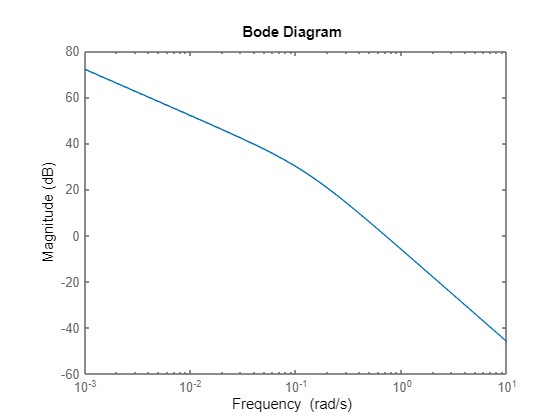

bodemag(Hf)

### Computing the P controller

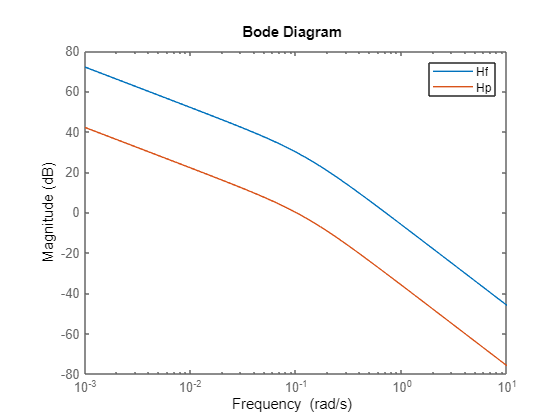

Wco = 0.7; % cut-off frequency
Wc = 1/8; % corner frequency
o = 0.1; % overshoot
dr = abs(log(o))/sqrt(log(o)^2+pi^2); % damping ratio
A = 1/4/dr^2;
N = 20*log10(A);
F = 27;
Vr = 10^((N-F)/20);
figure;
hold on;
bodemag(Hf)
bodemag(Vr*Hf)
hold off;
legend("Hf","Hp");

Wco = 0.1;
Wn = 2*dr*Wco;
tr = 4/dr/Wn % settling time

tr = 57.2305

   $t_r \le 5$ "False"

Cv = -36 % the velocity coefficient read at w=1

Cv = -36

   $c_v \ge 3$ "False"

deltaWb = Wco % the bandwidth

deltaWb = 0.1000

   $\Delta w_b \le 15$ "True"

### Computing the PD controller

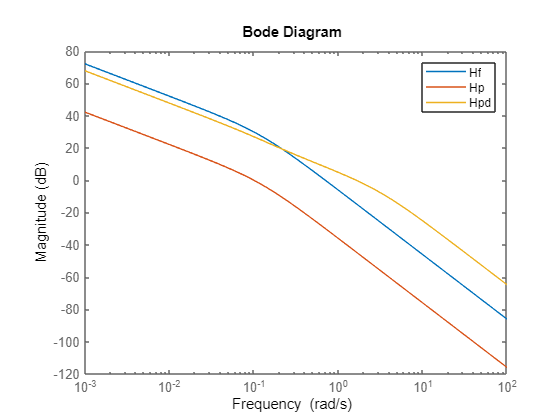

trstar = 3;
Wco2 = 2/dr^2/trstar;
Wco = 2/dr^2/tr;
Vr2 = Vr*Wco2/Wco;
td = 6;
Tn = td*trstar/tr;
figure;
hold on;
bodemag(Hf)
bodemag(Vr*Hf)
bodemag(Vr2*Hf*tf([td 1],[Tn 1]))
hold off;
legend("Hf","Hp","Hpd");

cv = 4.8 % the velocity coefficient read at w=1

cv = 4.8000

     $c_v \ge 3$ "True"

figure;
% step(feedback(Vr2*Hf*tf([td 1],[Tn 1]),1))